clc; clear; close all;
cd 'G:\Jiaxu Song\Ag_in_warter\new Ag sample\CC400\test2'

data = importdata("CC400_test2.txt");
z = data(:,3); v_change = 1008; %842

t = (0.1:0.1:length(z)/10)';

x_fit_0v = t(1:v_change);
y_fit_0v = z(1:v_change);

x_fit_v = t(v_change:end);
y_fit_v = z(v_change:end);

p_0v = polyfit(x_fit_0v,y_fit_0v,1);
p_v = polyfit(x_fit_v,y_fit_v,1);

y_fit_0v_new = x_fit_0v*p_0v(1) + p_0v(2);
y_fit_v_new = x_fit_v*p_v(1) + p_v(2);

k1 = p_0v(1)

k1 = -0.6025

k2 = p_v(1)

k2 = -0.4677

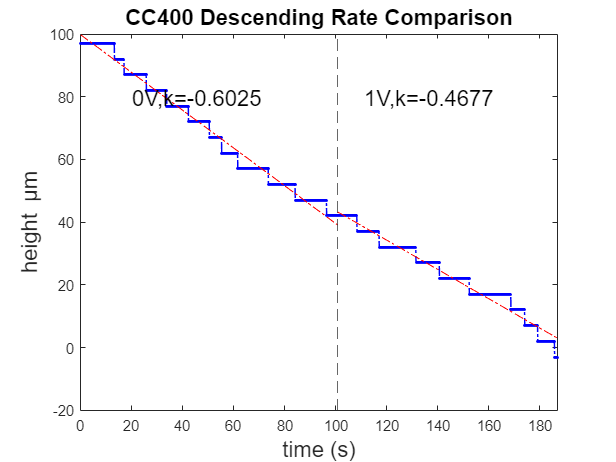


figure(1)
plot(t,z,'b-.',LineWidth=1,Marker='.'); hold on
plot(x_fit_0v,y_fit_0v_new,'r-.',LineWidth=0.5); hold on
plot(x_fit_v,y_fit_v_new,'r-.',LineWidth=0.5); hold on

xline(t(v_change),'--'); hold on
text(t(round(v_change/5)),80,'0V,k=-0.6025','FontSize',15); hold on
text(t(round(v_change/5))*5.5,80,'1V,k=-0.4677','FontSize',15); hold off
xlabel('time (s)',FontSize=15);
ylabel('height \mum',FontSize=15);
title('CC400 Descending Rate Comparison',FontSize=15)
xlim([0 max(t)])